dir = readtable("PtDirectorySimple.xlsx")

dir = 7×6 table
    Patient    Hemisphere            JsonSurvey                     JsonStream             StartIndex    DoubleBattery
    _______    __________    ___________________________    ___________________________    __________    _____________

       1         {'l'}       {'pt1_0524_l_survey.json' }    {'pt1_0524_l_stream.json' }        7               1      
       1         {'r'}       {'pt1_0524_r_survey.json' }    {'pt1_0524_r_stream.json' }        7               1      
       2         {'l'}       {'pt2_0604_rl_survey.json'}    {'pt2_0604_rl_stream.json'}        1               0      
       2         {'r'}       {'pt2_0604_rl_survey.json'}    {'pt2_0604_rl_stream.json'}        1               0      
       3         {'l'}       {'pt3_0630_l_survey.json' }    {'pt3

jsonFiles = dir.JsonSurvey{1}; 
side = dir.Hemisphere{1}; 
startIndex = dir.StartIndex(1); 
js = jsondecode(fileread(jsonFiles)); 
outTABLE = extractSurveyData(js, side, startIndex);
%[sumTABLEp, sumTABLEh] = createSumTable(outTABLE)

%dabest('TwoGroups_sample.csv') 

goal: using a single channel, get the data from outTABLE and get beta, down sample appropriately, live life ! 

lets go w 0.25 Hz resolution, = 33-13 = freqnecy spectrum = 20 * 4 (0.25Hz is 4 samples per second) = 80 

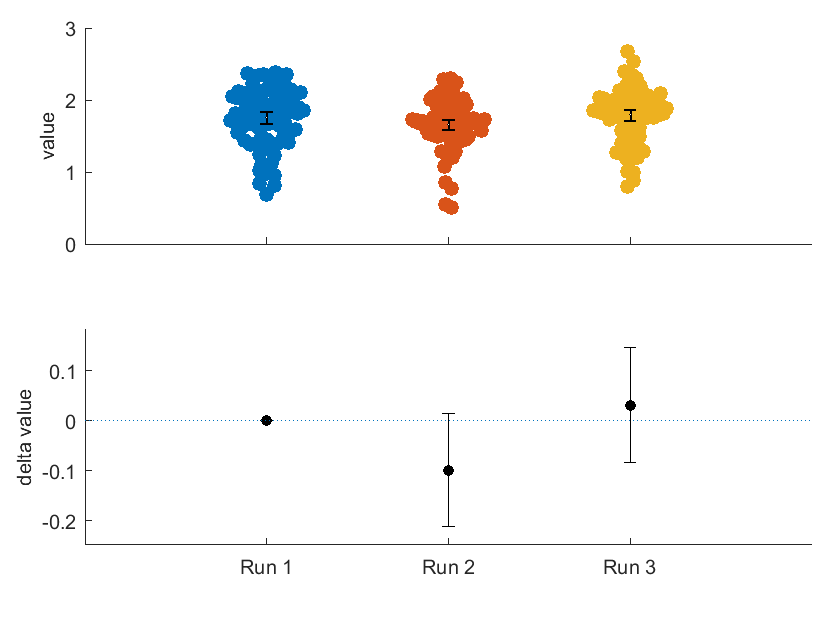

ans = 5×4 table
            Group              Value               CIs               N 
    _____________________    _________    ______________________    ___

    {'Run 1'            }       1.7628       1.6755       1.8437     82
    {'Run 2'            }       1.6637       1.5853       1.7346     82
    {'Run 3'            }       1.7928         1.71       1.8684     82
    {'Run 2 minus Run 1'}    -0.099133     -0.21221     0.014805    NaN
    {'Run 3 minus Run 1'}     0.030014    -0.082669      0.14713    NaN


runs = zeros(82,3);
ids = cell(82,3);
for i = 1:3 
powerdata = outTABLE.PF_Data{i};
%find freq vales of interest
fbeta = powerdata.Frequency > 13 & powerdata.Frequency < 33;
betapwr = powerdata.Power(fbeta);
% means(:, i) = betapwr;
% %meanst(:, i) = thetapwr;
% %modify data for KS test
betapwr = abs(log10(betapwr));
betapwr = downsample(betapwr, 10);
x = length(betapwr); 
id = append("Run ", num2str(i)); 
runs(:,i) = betapwr; 
ids(:,i) = {id}; 
end 
x = 82; 
run_export = ([runs(1:x), runs(x+1:2*x), runs(2*x+1:3*x)])'; 
id_export = ([ids(1:x), ids(x+1:2*x), ids(2*x+1:3*x)])'; 
Tid = array2table(id_export); 
Trun = array2table(run_export); 
T = [Tid, Trun]; 
T.Properties.VariableNames = {'Identifiers', 'Values'}; 
writetable(T, 'table1.csv')
dabest('table1.csv')